# Лабораторная работа №2

Метод наименьших квадратов.

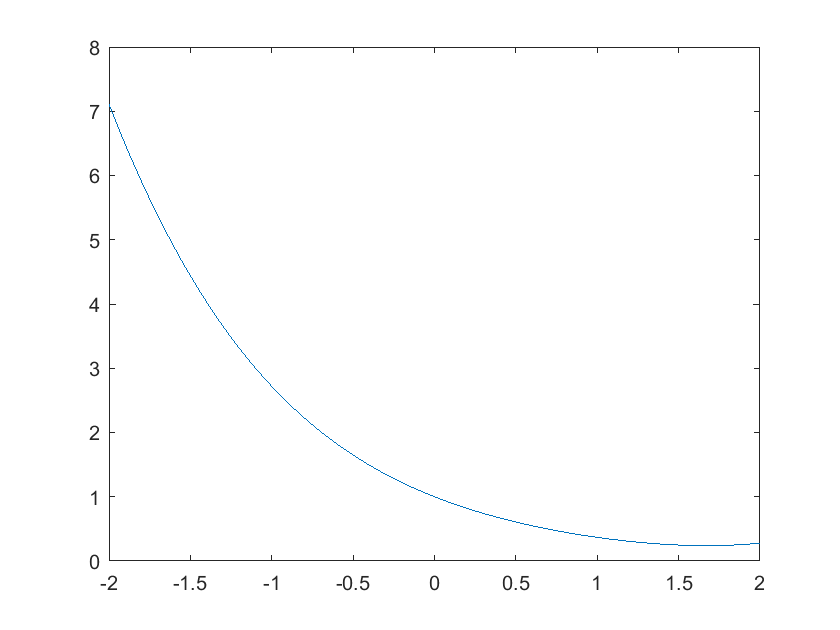

n_max = 5;
 
f = @(x) exp(-x);
x = linspace(-1, 1, n_max);
x0 = linspace(-2, 2, 100);
y = f(x);
y0 = mnk(x, y, x0, n_max-1);
plot(x0, y0)

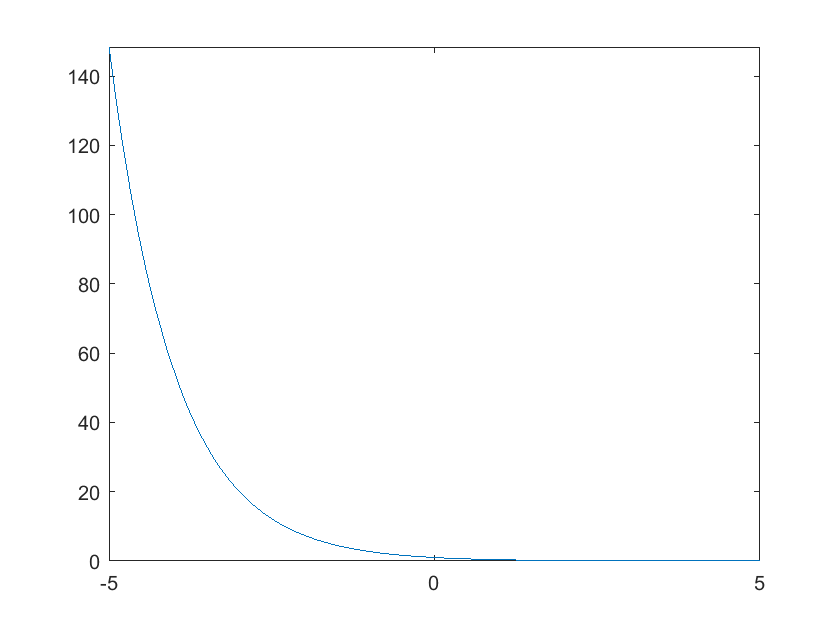

fplot(f)

Построение зависимости погрешности от количества узлов.

n_max = 100;
 
f = @(x) exp(-x);
E = [];
for n = 2:n_max
    E(n) = get_err_cont(f, [-1, 1], n, "rvn", n_max - 1);
end

disp('Равномерная сетка, непрерывная функция');

Равномерная сетка, непрерывная функция


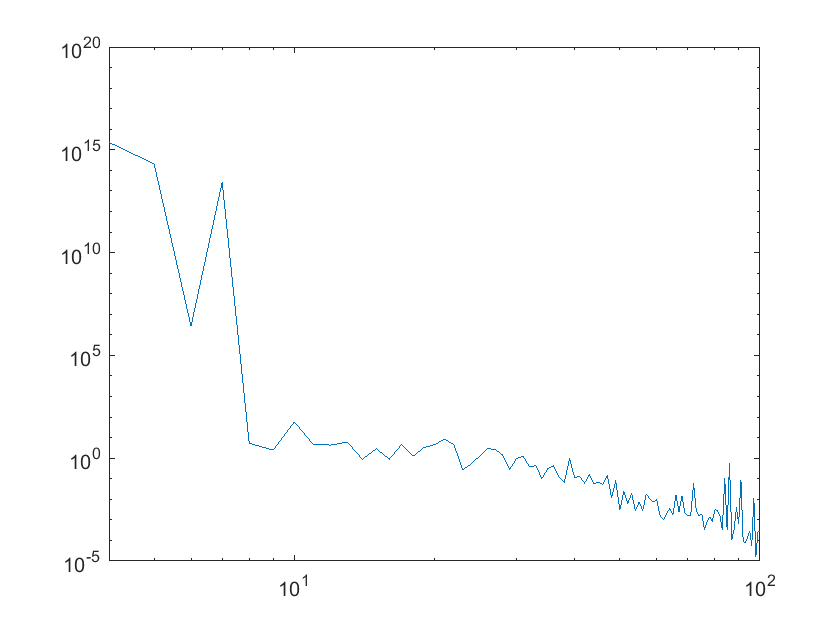

loglog(1:n_max, E)

function y0 = mnk(x, y, x0, k)
    y0 = zeros(size(x0));
    A = zeros(k+1);
    for i = 1:k+1
        for j = 1:k+1
            if i == j
                A(i, j) = sum(x.^(2*(i-1)));
            else
                A(i, j) = sum(x.^(i+j-2));
            end
        end
    end
    A(1, 1) = max(size(x));
    B = zeros([k+1, 1]);
    for i = 1:k+1
        c = 0;
        for j = 1:max(size(x))
           c = c + x(j)^(i-1)*y(j);
        end
        B(i) = c;
    end
    th = A \ B;
    for i = 1:max(size(x0))
        c = 0;
        for j = 2:size(th)
            c = c + th(j)*x0(i)^(j-1);
        end
       y0(i) =  th(1) + c;
    end
end

function delta = get_error(x_tr, x_pred)
    a = x_tr' - x_pred';
    a = abs(a);
    delta = max(a);
end

function eps = get_err_cont(f, dd, n, type_s, k)
    if type_s == "rvn"
        X = linspace(dd(1), dd(2), n);
        Y = f(X);
        xx = [];
        xx = linspace(dd(1), dd(2), 100*n);
        yy = mnk(X, Y, xx, k);
        Y = f(xx);
        eps = get_error(Y, yy);
    elseif type_s == "cheby"
        syms t;
        X = solve(cos(n*acos(t)) == 0, 'Real', true);
        X = vpa(X);
        X = sort(X);
        Y = f(X);
        xx = [];
        xx = linspace(dd(1), dd(2), 100*n);
        yy = mnk(X, Y, xx, k);
        Y = f(xx);
        eps = get_error(Y, yy);
    end
end
